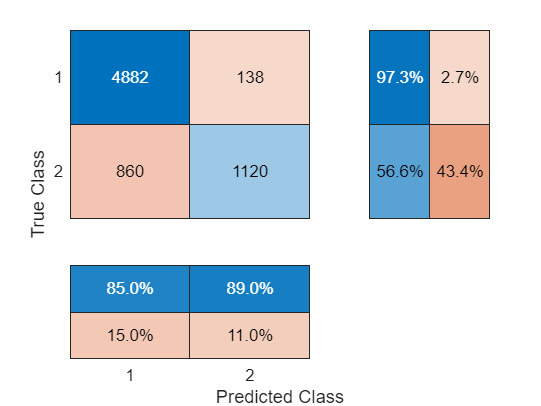

%Bring in variables for Ensemble Voting

load('myVariables.mat')

%Predictions are the prediction arrays of each model. Saved after running
%each model and then loaded in 

Predictions = [kNN, GLM, SVM, DT, RBF];

final_decisions = ensemble_voting(Predictions);

function Final_decision = ensemble_voting(Predictions)
    % Initialize Final_decision vector to store the ensemble decisions
    Final_decision = zeros(size(Predictions, 1), 1);

    % Loop through each prediction instance
    for row = 1:size(Predictions, 1)
        % Count the votes for each model outcome
        vote_count = sum(Predictions(row, :));

        % Make the final decision based on majority voting
        if vote_count > size(Predictions, 2) / 2
            Final_decision(row) = 1; % If more than half of the classifiers vote for 1
        else
            Final_decision(row) = 0; % If half or less of the classifiers vote for 1
        end
    end
end

CFM_FN = confusionmat(dep_Var_test, final_decisions);
confusionchart(CFM_FN, 'RowSummary','row-normalized', 'ColumnSummary', 'column-normalized')

CFM_Stats(dep_Var_test, final_decisions)

Confusion Matrix:
        4882         138
         860        1120

Overall accuracy = 0.85743


ans = 2×6 table
    accuracy    precision    recall     Fscore     sensitivity    specificity
    ________    _________    _______    _______    ___________    ___________

    0.85743      0.85023     0.97251    0.90727      0.97251        0.56566  
    0.85743       0.8903     0.56566    0.69179      0.56566        0.97251  
